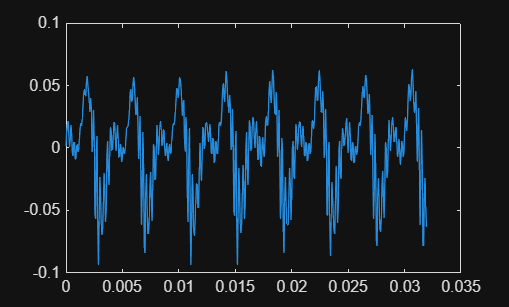

% Experiental DSP Exercise 2

% Part A
[x, F] = audioread("audio.wav");

% Compute duration of audio
duration = length(x) / F;

% Create time axis in seconds
t = (0:length(x)-1)/F;

% Plot the signal
figure
plot(t, x)


% Find the indices of the peaks in the signal.
% The first output (ignored with ~) is the peak value. The second is the index.
[~, peak_indices] = findpeaks(x);

% Calculating the period in samples by finding the difference between the first two peak indices.
period_in_samples = peak_indices(2) - peak_indices(1)

period_in_samples = 4


% Convert the period from samples to seconds using the sampling rate F.
approx_period = period_in_samples / F;

% Display the result in the command window.
disp(['The approximate period of the signal is: ', num2str(approx_period), ' seconds']);

The approximate period of the signal is: 0.00025 seconds


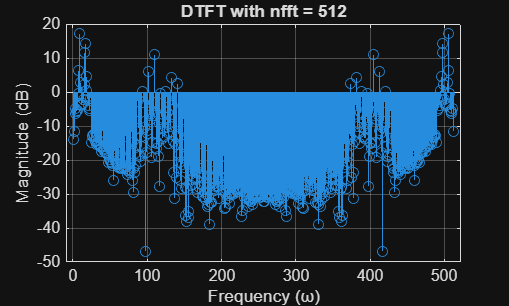

% Part B
nfft_1 = 512;
nfft_2 = 1024;

% Get the FFTs
X_1 = fft(x, nfft_1);
X_2 = fft(x, nfft_2);

% Frequency vectors
w1 = (0:nfft_1-1) * (2*pi/nfft_1);
w2 = (0:nfft_2-1) * (2*pi/nfft_2);

% STEM 1
figure(1)
stem(20*log10(abs(X_1)));
title('DTFT with nfft = 512');
xlabel('Frequency (ω)');
ylabel('Magnitude (dB)');
grid on;

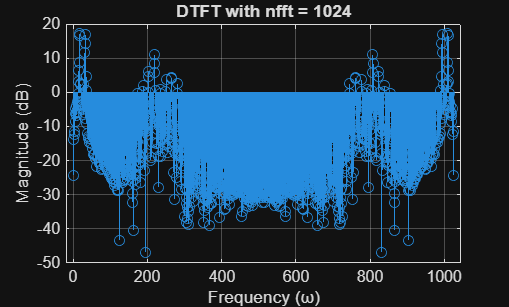


% STEM 2
figure(2)
stem(20*log10(abs(X_2)));
title('DTFT with nfft = 1024');
xlabel('Frequency (ω)');
ylabel('Magnitude (dB)');
grid on;


% Display the result in the command window.
disp(['The mid point for both signals are at ω = π']);

The mid point for both signals are at ω = π


disp(['Parts of both plots from 0 to π and π to 2π are mirror images of each other']);